%Jacob V Sanoj PES1UG20EC083
%Sampling

clc;
clear;
close all;

tr=0.001;
ts=0.02;
t=0:0.001:1;
xt=cos(2*pi*t)+2*sin(2*pi*t);
n=0:0.02:1;

Nfactor= round(ts/tr);
bw=10;

%generating the impulse train or the ideal factor
p=ones(1,length(xt));
p=downsample(p,Nfactor);
p=upsample(p,Nfactor);
p=p(1:length(xt));
xs=xt.*p;

%plotting xt
subplot(3,1,1)

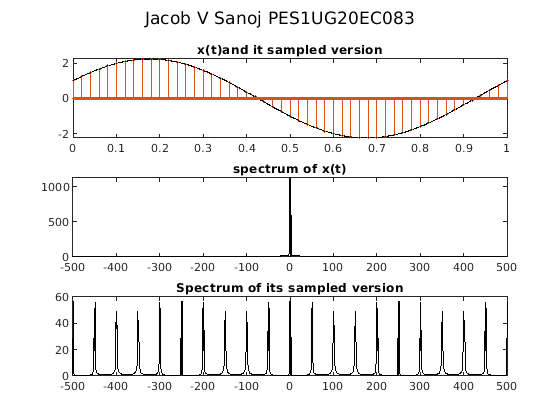

plot(t,xt,'k');
hold on
stem(t,xs,'Markersize',1);
title('x(t)and it sampled version');
sgtitle('Jacob V Sanoj PES1UG20EC083');

%finding the spectrum of x(t)and its sampled version
Nfft=2^ceil(log2(length(xt)));
fmax=1/(2*0.001);
faxis=linspace(-fmax,fmax,Nfft);
X=fftshift(fft(xt,Nfft));
Xs=fftshift(fft(xs,Nfft));

subplot(3,1,2)
plot(faxis,abs(X),'k');
title('spectrum of x(t)');

subplot(3,1,3)
plot(faxis,abs(Xs),'k');
title('Spectrum of its sampled version');

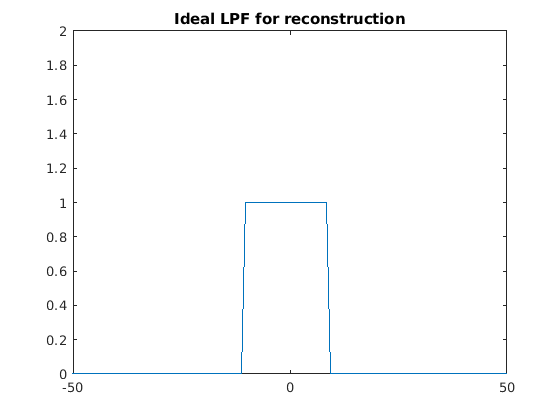


%defining and plotting the ideal LPF for the reconstruction

Hlpf=zeros(1,Nfft);
Hlpf(Nfft/2-bw:Nfft/2+bw-1)=1;
figure;
plot(faxis,Hlpf);
axis([-50, 50, 0, 2]);
title(" Ideal LPF for reconstruction ");

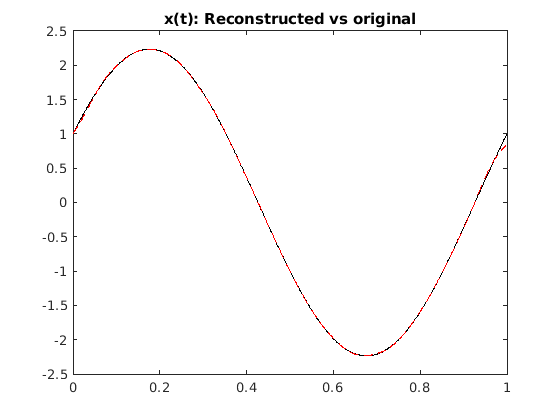



% Reconstructing x(t)

Xr = Nfactor * Hlpf.*Xs;  
%Multiplying the spectrum of the sampled signal with the ideal LPF response, along with scaling

xr = real(ifft(fftshift(Xr)));
xr = xr(1:length(xt));
% Plotting the reconstructed x(t) and comparison with the original x(t)

figure;
plot(t, xt, '-k');
hold on
plot(t, xr, '--r')
title(" x(t): Reconstructed vs original ");